# 第6章　微分方程

## **6.1　微分方程模型**

### 例1　空气冷却问题

　　物体在空气中的冷却速度与物体和空气的温差成正比，如果物体在20min内有100℃冷却到60℃，那么经过多长时间此物体的温度将达到30℃？

　　解：记温度为$T$、时间为$t$、冷却常数为$k$，根据牛顿冷却定律，得


$$\left\lbrace \begin{array}{c}
\frac{\partial T}{\partial t}=-k\left(T-20\right)\\
T\left(0\right)=100\\
T\left(\frac{1}{3}\right)=60
\end{array}\right.$$


解得$T=80\times {\left(\frac{1}{2}\right)}^{3t} +20$，且$T\left(1\right)=30$，即经过1小时后温度可以降低到30℃。

### 例2　目标跟踪问题

　　设位于坐标原点的甲舰项位于$x$轴上点$A\left(1,0\right)$处的乙舰发射导弹，导弹始终对准乙舰。如果乙舰以最大的速度$v_0$（$v_0$是常数）沿平行于$y$轴的直线行驶，导弹的速度是$5v_0$，求导弹的运行曲线。又乙舰形式多远时，导弹将它击中？

　　解：记导弹轨迹为$y=y\left(t\right)$，根据题意得


$$\left\lbrace \begin{array}{c}
v_0 t=\left(1-x\right)y^{\prime } +y\\
\int_0^x \sqrt{1+{y^{\prime } }^2 }\;\mathit{dx}=5v_0 t\\
y\left(0\right)=0\\
y^{\prime } \left(0\right)=0
\end{array}\right.$$


解得$y=-\frac{5}{8}{\left(1-x\right)}^{\frac{4}{5}} +\frac{5}{12}{\left(1-x\right)}^{\frac{6}{5}} +\frac{5}{24}$为导弹轨迹方程。当$x=1$时，$y=\frac{5}{24}$，即当乙舰行驶到$\left(1,\frac{5}{24}\right)$处被导弹击中，击中时刻为$t=\frac{y}{v_0 }=\frac{5}{24v_0 }$。当$v_0 =1$时，$t\approx 0\ldotp 21$。

## **6.3　用MATLAB解微分方程**

### 例4　解微分方程


$$\left\lbrace \begin{array}{c}
\frac{\partial^2 x}{\partial t^2 }-1000\left(1-x^2 \right)\frac{\partial x\;}{\partial t}+x=0\\
x\left(0\right)=0\\
x^{\prime } \left(0\right)=1
\end{array}\right.$$


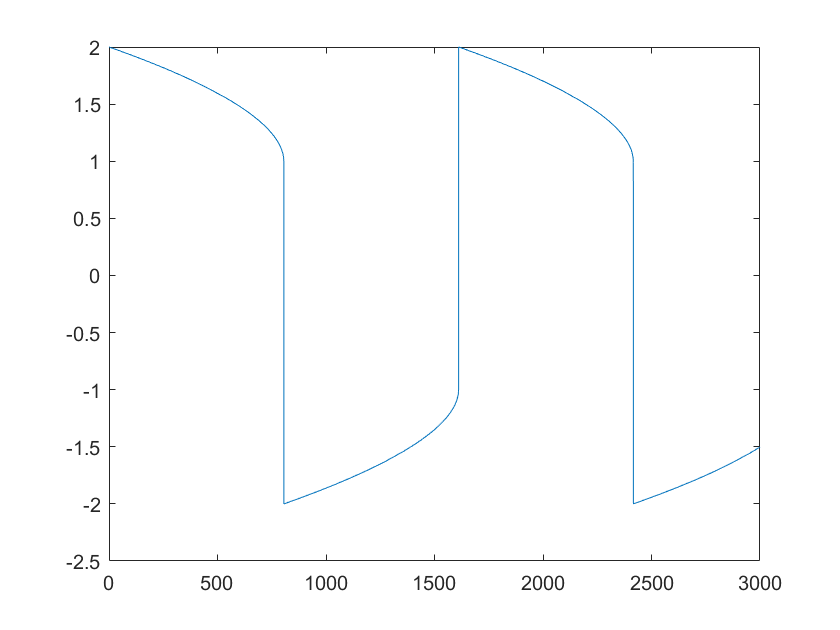

clear T Y
[T, Y] = ode15s(@vdp1000, [0, 3000], [2, 0]);
plot(T, Y(:, 1), "-");

### **例6　求6.1节例2目标跟踪问题的数值解**

　　解：（1）列方程


$$\left\lbrace \begin{array}{cc}
{\left(\frac{\partial x}{\partial t}\right)}^2 +{\left(\frac{\partial y}{\partial t}\right)}^2 =w^2  & \left(1\right)\\
\left\lbrack \begin{array}{c}
\frac{\partial x}{\partial t}\\
\frac{\partial y}{\partial t}
\end{array}\right\rbrack =\lambda \left\lbrack \begin{array}{c}
X-x\\
Y-y
\end{array}\right\rbrack  & \left(2\right)\\
{\left(\frac{\partial x}{\partial t}\right)}^2 +{\left(\frac{\partial y}{\partial t}\right)}^2 =\lambda^2 \left\lbrack {\left(X-x\right)}^2 +{\left(Y-y\right)}^2 \right\rbrack  & \left(3\right)\\
X=1 & \left(4\right)\\
Y=t & \left(5\right)
\end{array}\right.$$


解得


$$\left\lbrace \begin{array}{c}
\frac{\partial x}{\partial t}=\frac{5}{\sqrt{{\left(1-x\right)}^2 +{\left(t-y\right)}^2 }}\left(1-x\right)\\
\frac{\partial y}{\partial t}=\frac{5}{\sqrt{{\left(1-x\right)}^2 +{\left(t-y\right)}^2 }}\left(t-y\right)\\
x\left(0\right)=0\\
y\left(0\right)=0
\end{array}\right.$$


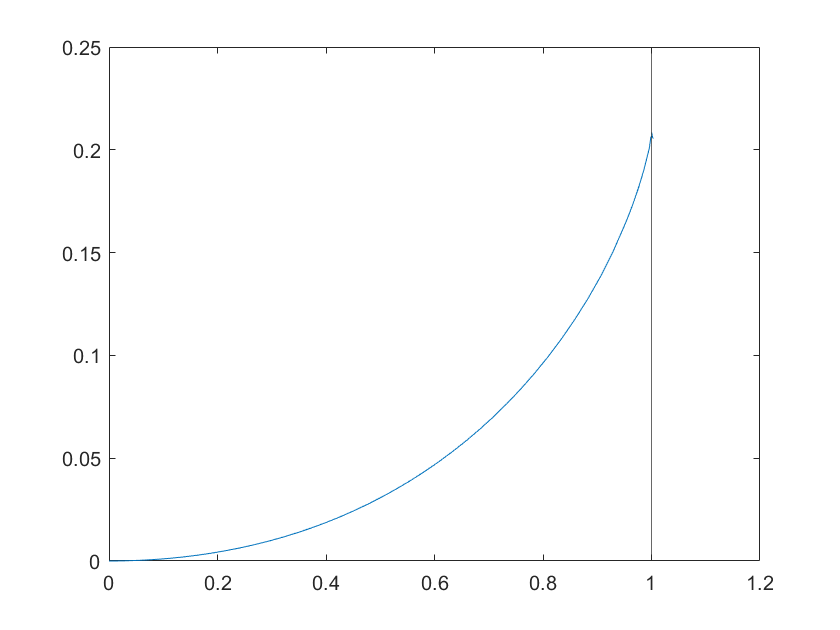

clear t0 tf t y
t0 = 0;
tf = 0.21;
[~, y] = ode45(@eq2, [t0, tf], zeros(1, 2));
plot(y(:, 1), y(:, 2), "-");
xline(1);

## 6.6　习题

### 1. 污染物降解问题

　　设一容积为$V$（$m^3$）的大湖受到某种物质的污染，污染物均匀地分布在湖中。若从某时刻起污染源被切断，设湖水更新的速率是$r$（$m^3 /\mathrm{天}$），是建立求污染物浓度下降至原来的$5%$需要多少时间的数学模型。美国密西根湖的溶剂为$4\;781\times {10}^9$（$m^3$），湖水的流量为$3\ldotp 663\;959\;132\times {10}^{10}$（$m^3 /\mathrm{天}$），求污染中止后，污染物浓度下降到原来的$5%$所需要的时间。

　　解：设$t$时湖区污染物浓度为$W\left(t\right)$、$m$为水源污染浓度、$r$为湖水更新速率、$V$为湖区容积。考虑时间段$\left\lbrack t,t+\Delta t\right\rbrack$，根据质量守恒定律得


$$V\left\lbrack W\left(t+\Delta t\right)-W\left(t\right)\right\rbrack =\mathrm{rm}\Delta t-\int_t^{t+\Delta t} \mathit{rW}\left(s\right)\;\mathit{ds}$$


令$\Delta t\to 0$，则


$$\left\lbrace \begin{array}{c}
\frac{\partial W}{\partial t}=\frac{\mathit{rm}-\mathit{rt}}{V}\\
W\left(0\right)=W_0 
\end{array}\right.$$


clear t W(t) m r V W_0 equations conditions origin
syms t W(t) m r V W_0
equations = (diff(W, t) == (r * m - r * W) / V);
conditions = (W(0) == W_0);
origin = dsolve(equations, conditions)

$$origin = m+{\mathrm{e}}^{-\frac{r\,t}{V}}\,\left(W_{0}-m\right)$$

m = 0;
r = 3.663959132e10;
V = 4781e9;
W_0 = 1;
vpa(solve(eval(origin) == 0.05, t))

$$ans = 390.90490597376103428693494274317$$